# Cviceni 5

## Histogram

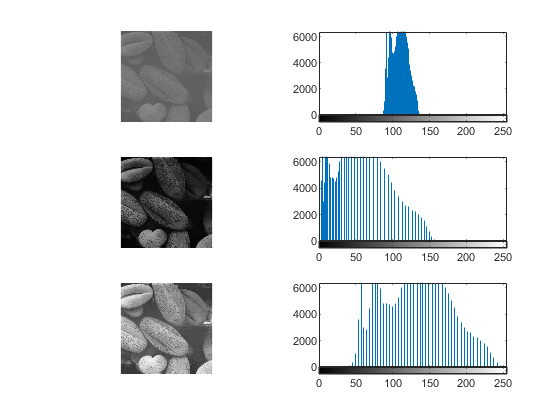

% imhist

I1 = imread('pic1.png');
I2 = imread('pic2.png');
I3 = imread('pic3.png');

figure,
subplot(3,2,1)
imshow(I1);
subplot(3,2,2)
imhist(I1)

subplot(3,2,3)
imshow(I2);
subplot(3,2,4)
imhist(I2)

subplot(3,2,5)
imshow(I3);
subplot(3,2,6)
imhist(I3)

## Úkol k zamysleni

jakym zpusobem se zmeni histogram obrazku, pri provedeni techto operaci:

- zmena jasu

- zmena kontrastu

- negativ obrazku

- gamma korekce s hodnotou < 1

- gamma korekce s hodnotou > 1

f = imread('picture1.png');

### Zmena jasu

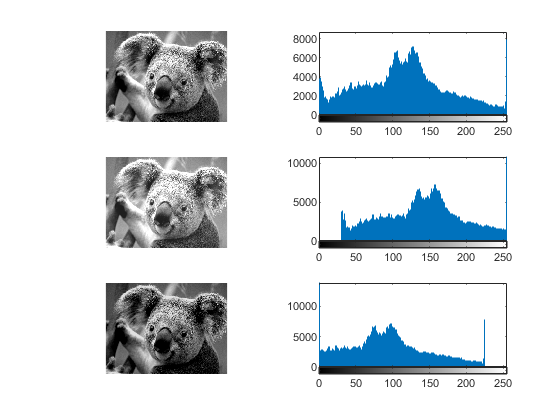

k1=30;
k2 = -30;

g1 = f + k1;
g2 = f + k2;

figure,
subplot(3,2,1)
imshow(f);
subplot(3,2,2)
imhist(f)
subplot(3,2,3)
imshow(g1);
subplot(3,2,4)
imhist(g1)
subplot(3,2,5)
imshow(g2);
subplot(3,2,6)
imhist(g2)

### Zmena kontrastu

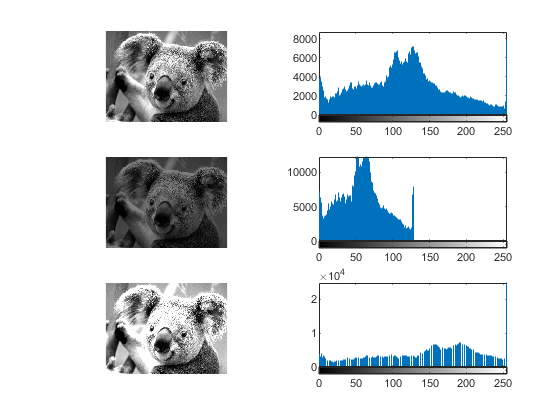

c1=0.5;
c2 = 1.5;

g3 = c1*f;
g4 =c2*f;

figure,
subplot(3,2,1)
imshow(f);
subplot(3,2,2)
imhist(f)
subplot(3,2,3)
imshow(g3);
subplot(3,2,4)
imhist(g3)
subplot(3,2,5)
imshow(g4);
subplot(3,2,6)
imhist(g4)

### Negativ obrazku

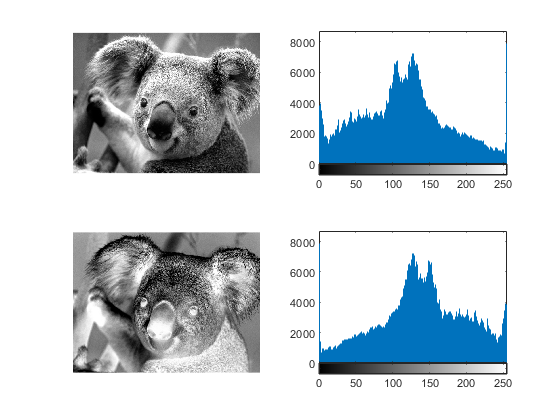

g5 =255 - f;

figure,
subplot(2,2,1)
imshow(f);
subplot(2,2,2)
imhist(f)
subplot(2,2,3)
imshow(g5);
subplot(2,2,4)
imhist(g5)

### Gamma korekce

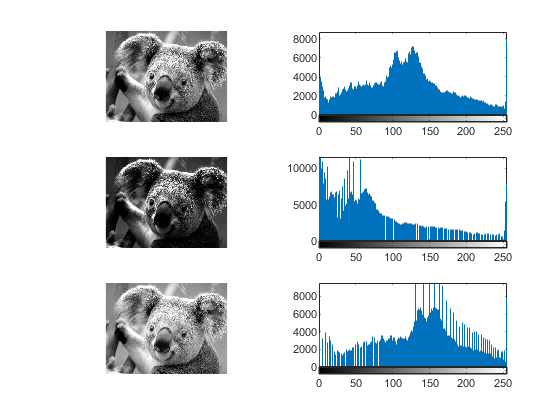

gam1 = 2;
gam2 = 0.7;

g6 = double(f).^gam1;
g7 = double(f).^gam2;

g6 = uint8(255*(g6/max(max(g6))));
g7 = uint8(255*(g7/max(max(g7))));

figure,
subplot(3,2,1)
imshow(f);
subplot(3,2,2)
imhist(f)
subplot(3,2,3)
imshow(g6);
subplot(3,2,4)
imhist(g6)
subplot(3,2,5)
imshow(g7);
subplot(3,2,6)
imhist(g7)

## Prahovani

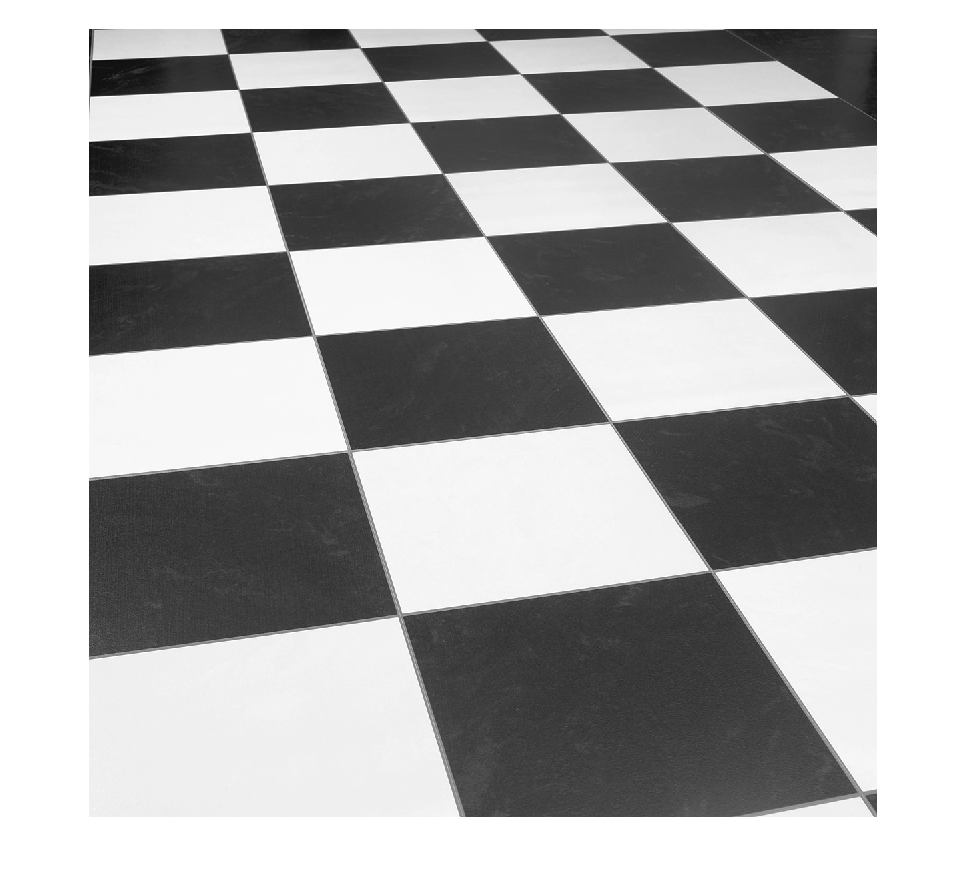

I = rgb2gray(imread('chess.jpg'));

figure,
imshow(I);

### Experimentalni vyber prahu

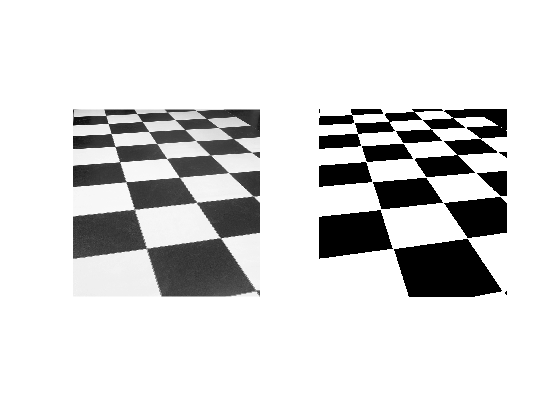

J = I>100;

figure,
subplot(1,2,1)
imshow(I);
subplot(1,2,2)
imshow(J);

### Prah na zaklade znalosti histogramu obrazku

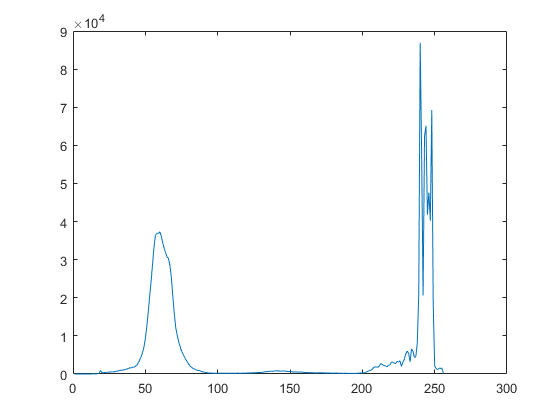

histogramI = imhist(I);

figure,
plot(histogramI);

### Kumulativní histogram

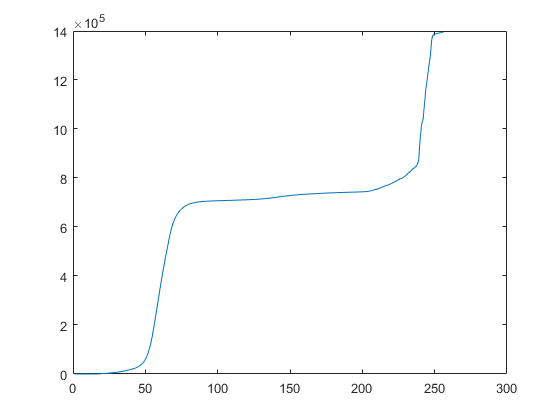

[pocet,X] = imhist(I);
cumh = cumsum(pocet);

figure,
plot(cumh);

### prah 50%

velikost = size(I,1) * size(I,2);
prah = round(velikost/2);
prah_index = find(cumh>=prah,1,'first');
display(prah_index);

prah_index = 83

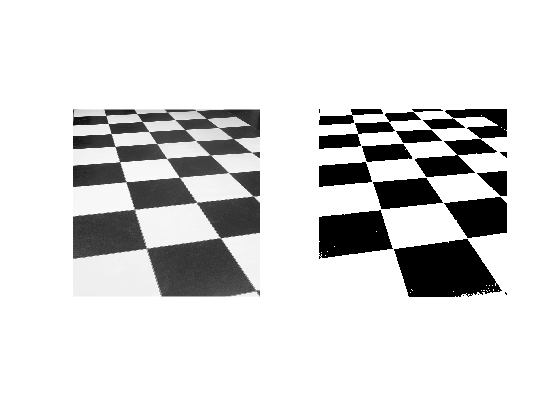

J = I>prah_index;

figure,
subplot(1,2,1)
imshow(I);
subplot(1,2,2)
imshow(J);

## Vicenasobne prahovani

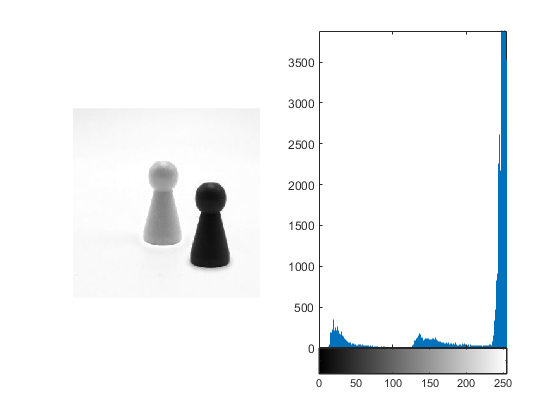

% g(x,y)     =  a pro f(x,y) > T1 (pozadí)
%            =  b pro f(x,y) <= T1 a f(x,y) > T2 (objekt 1)
%            =  c pro f(x,y) <= T2 (objekt 2)
% vetšinou je a=1, b = 0.5 a c = 0

f2 = rgb2gray(imread('figurka2.jpg'));

figure,
subplot(1,2,1)
imshow(f2);
subplot(1,2,2)
imhist(f2);

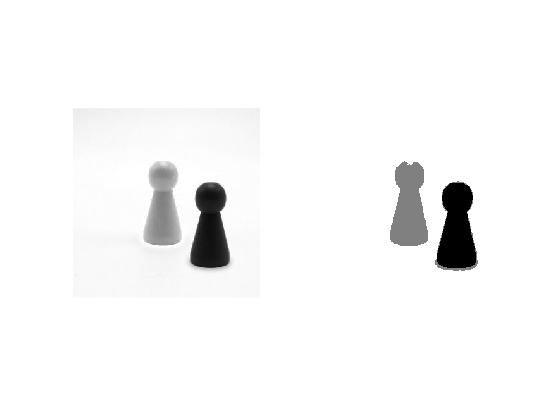

T1 = 220;
T2 = 100;
g2 = 0.5*(f2 >T1) + 0.5*(f2>T2);

figure,
subplot(1,2,1)
imshow(f2);
subplot(1,2,2)
imshow(g2);

## Lokalni prahovani

f3 = imread('lokalni.jpg');
T = 46

T = 46

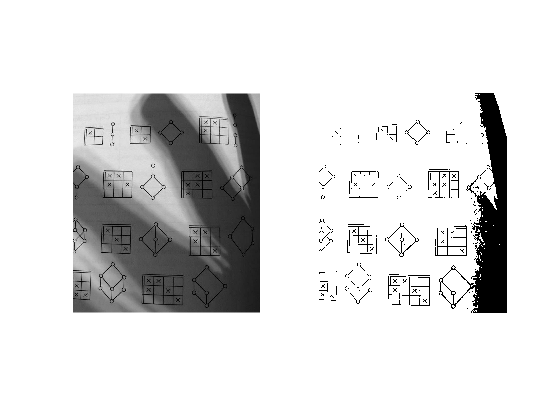


g3 = f3 > T;

figure,
subplot(1,2,1), imshow(f3);
subplot(1,2,2), imshow(g3);

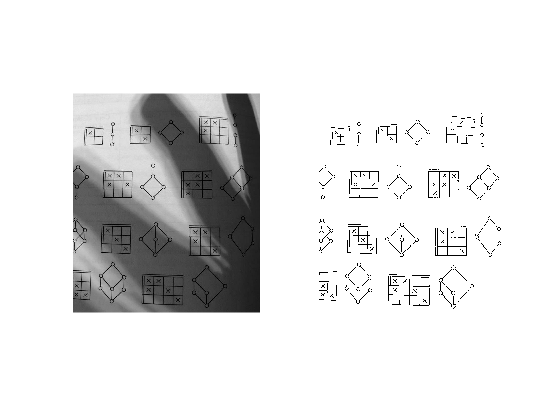

% Pro kazdy bod pocitame prahovou hodnota v zavislosti na okolnich bodech.
% (jedna se o filtrovani, viz dale)

f4=im2double(f3);
nhood = ones(3)/9;
g_std = stdfilt(f4);
g_mean = imfilter(f4,nhood);

% a, b jsou nezáporné konstanty, které v součtu dávají 1
a=0.3;
b=1-a;

T = a*g_std + b*g_mean;

g4 = f4 > T;
subplot(1,2,1), imshow(f4);
subplot(1,2,2), imshow(g4);

## Vyrovnavani histogramu

I1 = imread('pic1.png');
I2 = imread('pic2.png');
I3 = imread('pic3.png');

figure,
subplot(3,2,1)
imshow(I1);
subplot(3,2,2)
imhist(I1)

subplot(3,2,3)
imshow(I2);
subplot(3,2,4)
imhist(I2)

subplot(3,2,5)
imshow(I3);
subplot(3,2,6)
imhist(I3)

### Obrazek pic1.png

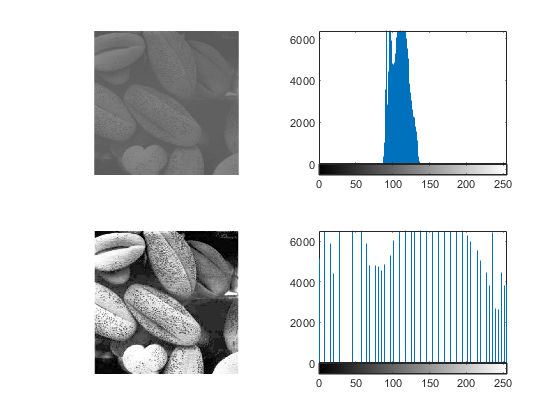

% J = histeq(I);
J1 = histeq(I1);

figure,
subplot(2,2,1)
imshow(I1);
subplot(2,2,2)
imhist(I1)
subplot(2,2,3)
imshow(J1);
subplot(2,2,4)
imhist(J1)

### Obrazek pic2.png

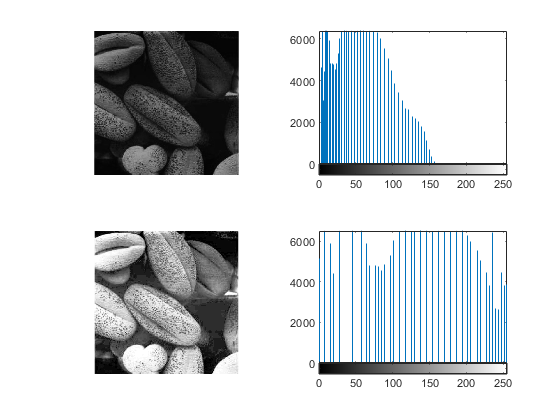

J2 = histeq(I2);

figure, 
subplot(2,2,1)
imshow(I2);
subplot(2,2,2)
imhist(I2)
subplot(2,2,3)
imshow(J2);
subplot(2,2,4)
imhist(J2)

### Obrazek pic3.png

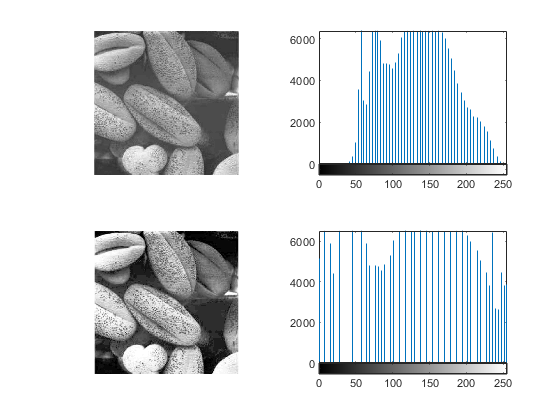

J3 = histeq(I3);

figure, 
subplot(2,2,1)
imshow(I3);
subplot(2,2,2)
imhist(I3)
subplot(2,2,3)
imshow(J3);
subplot(2,2,4)
imhist(J3)

## Specifikace histogramu

### Vytvoreni histogramu

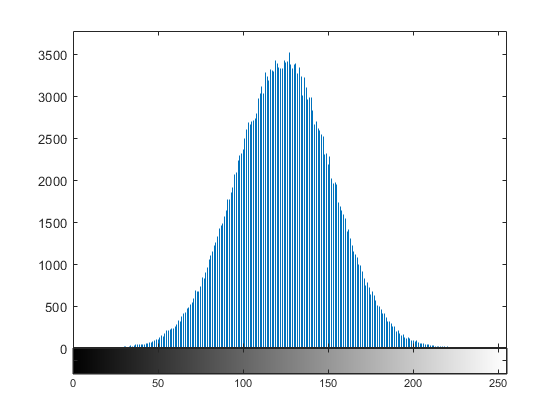

spechistobr = randn(size(I2));
minimum = min(min(spechistobr));
spechistobr = spechistobr + (0-minimum);
maximum = max(max(spechistobr));
spechistobr = 255*(spechistobr/maximum);
spechistobr = uint8(round(spechistobr));

figure, 
imhist(spechistobr)

### Specifikace histogramu

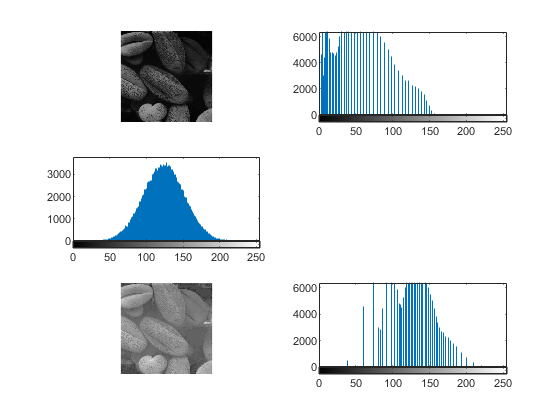

[COUNTS,X] = imhist(spechistobr);
Jspec = histeq(I2, COUNTS);

figure,
subplot(3,2,1)
imshow(I2);
subplot(3,2,2)
imhist(I2)
subplot(3,2,3)
imhist(spechistobr)
subplot(3,2,5)
imshow(Jspec);
subplot(3,2,6)
imhist(Jspec)

## Upravy obrazu - Operace s okolim (Filtrovani)

### Korelace

f = [0 0 0 1 0 0 0];
w = [1 2 3 2 8];

g = imfilter(f,w,'corr','same')

g =      0     8     2     3     2     1     0


### Konvoluce

f = [0 0 0 1 0 0 0];
w = [1 2 3 2 0];
g = imfilter(f,w,'conv','same')

g =      0     1     2     3     2     0     0


### Korelace ve 2D

f = [ 0 0 0 0 0; 0 0 0 0 0; 0 0 1 0 0; 0 0 0 0 0; 0 0 0 0 0];
w = [ 1 2 3; 4 5 6; 7 8 9];
g = imfilter(f,w,'corr','same')

g =      0     0     0     0     0
     0     9     8     7     0
     0     6     5     4     0
     0     3     2     1     0
     0     0     0     0     0


### Konvoluce ve 2D

g = imfilter(f,w,'conv','same')

g =      0     0     0     0     0
     0     1     2     3     0
     0     4     5     6     0
     0     7     8     9     0
     0     0     0     0     0


## Vyhlazovaci filtry

### Filtarce prumerovanim

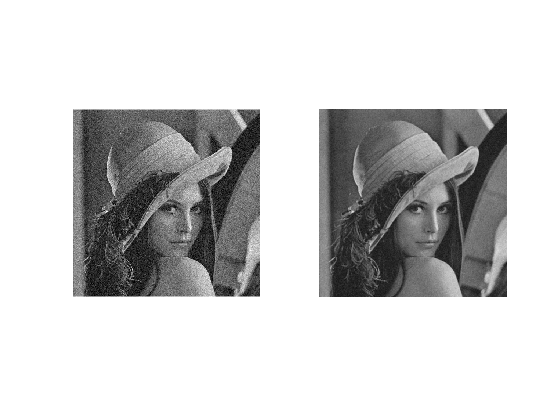

B = imread('lenagraysum.bmp');
w = 1/9 * [1 1 1; 
           1 1 1; 
           1 1 1];

C = imfilter(B,w,'corr','same');

figure,
subplot(1,2,1)
imshow(B);
subplot(1,2,2)
imshow(C)

## UKOL 1

Vytvorte prumerovaci filtry s velikostmi 3x3, 4x4, 5x5, 6x6 a 10x10 a porovnejte mezi sebou vysledky aplikace filtru na obrazek.

## UKOL 2 - k zamysleni

Na obrázek a.png jsou postupně aplikovány čtvercové průměrovací filtry o velikosti 30 (a), 34 (b) a 45 (c). Svislé čáry vlevo dole jsou na obrázcích (a) a (c) rozmazané, ale existuje mezi nimi jasný přechod. U obrázku (b)  znatelné nejsou navzdory tomu, že je velikost průměrovací masky znatelně menší, než v případě (b). Jak je to možné?

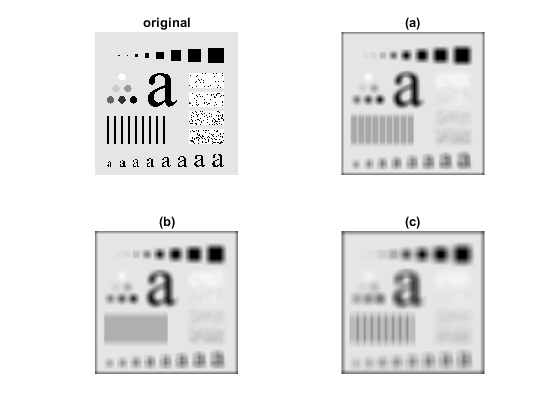

I = imread('a.png');

a = 30;
b = 34;
c = 45;

% Filtry predstavene ve cviceni lze vytvaret i pomoci funkce fspecial 
% (v ukolech ji ale nepouzivejte)
% help fspecial

Ha = fspecial('average',[a,a]);
Hb = fspecial('average',[b,b]);
Hc = fspecial('average',[c,c]);
A = imfilter(I,Ha);
B = imfilter(I,Hb);
C = imfilter(I,Hc);

figure,
subplot(2,2,1), imshow(I);
title('original');
subplot(2,2,2), imshow(A);
title('(a)');
subplot(2,2,3), imshow(B);
title('(b)');
subplot(2,2,4), imshow(C);
title('(c)');

### Vazene prumerovani

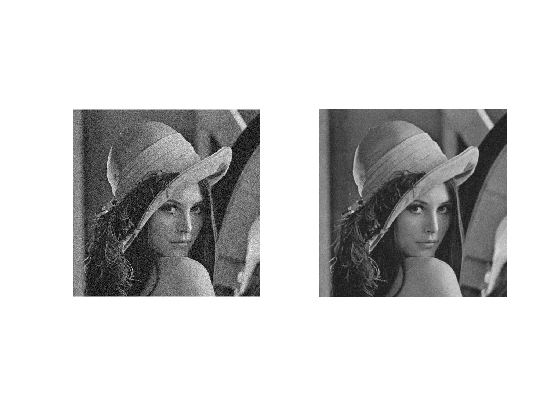

B = imread('lenagraysum.bmp');
w = 1/16 * [1 2 1; 
            2 4 2; 
            1 2 1];
C = imfilter(B,w,'corr','same');

figure,
figure,
subplot(1,2,1)
imshow(B);
subplot(1,2,2)
imshow(C)

### Medianova filtrace

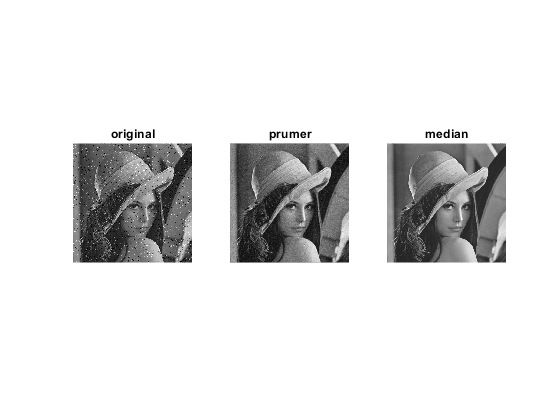

B = imread('lenagraysum2.bmp');
w = 1/9 * [1 1 1; 
           1 1 1; 
           1 1 1];
C = imfilter(B,w,'corr','same');

C2 = medfilt2( B,[3 3] );

figure
subplot(1,3,1)
imshow(B)
title('original')
subplot(1,3,2)
imshow(C,[])
title('prumer')
subplot(1,3,3)
imshow(C2,[])
title('median')

## UKOL 3

Vyberte vhodny filtr a odstrante (minimalizujte) nezadoucí informaci v obrazcich:

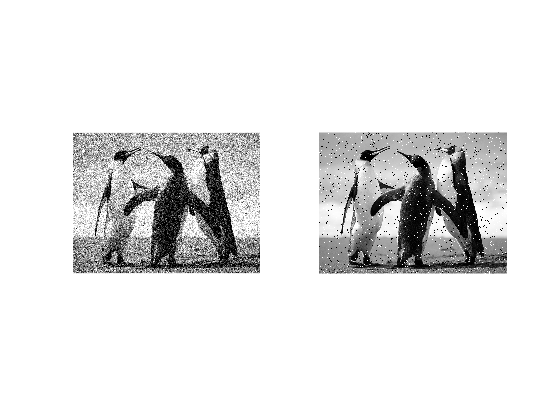

I1 = imread('cv5-img1.png');
I2 = imread('cv5-img2.png');

figure,
subplot(1,2,1)
imshow(I1);
subplot(1,2,2)
imshow(I2)

## Ostreni

I = imread('pastelkygray.jpg');
f = 1/36 * ones(6);
Iblur = imfilter(I,f,'corr','same');
mask = I - Iblur;
Isharp = I + 2* mask;

figure
subplot(2,2,1)
imshow(I,[])
subplot(2,2,2)
imshow(Iblur,[])
subplot(2,2,3)
imshow(mask,[])
subplot(2,2,4)
imshow(Isharp,[])

## Ostrici filtry

### Laplaceuv operator

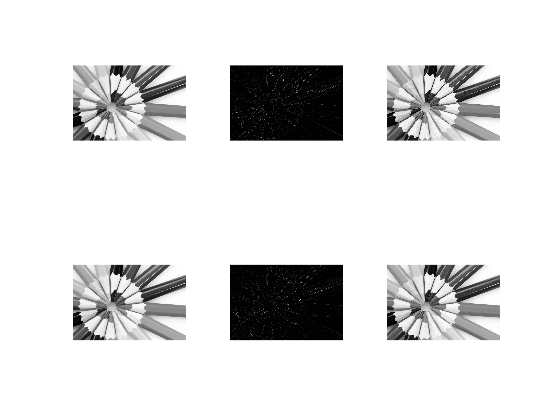

I = imread('pastelkygrayblurred.png');
w = -[-1 -1 -1; 
      -1 8 -1; 
      -1 -1 -1];
     
w2 = -[0 -1 0; 
       -1 4 -1; 
       0 -1 0];
C = imfilter(I,w,'corr','same');
C2 = imfilter(I,w2,'corr','same');


figure
subplot(2,3,1)
imshow(I,[])
subplot(2,3,2)
imshow(C,[])
subplot(2,3,3)
imshow(I-C,[])

subplot(2,3,4)
imshow(I,[])
subplot(2,3,5)
imshow(C2,[])
subplot(2,3,6)
imshow(I-C2,[])

#### Zvyrazneni hran - ostreni

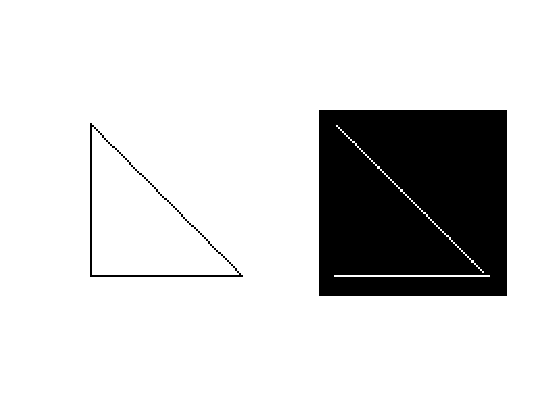

w2 = -[0 -1 0; 
      -1 3 -1; 
       0 -1 0];
C2 = imfilter(I,w2,'corr','same');


figure,
imshow(C2,[])

### Robertsuv operator 

I = imread('trojuhelnik.png');
w = [-1 -1; 
      1 1];
I2 = imfilter(I,w,'corr','same');

figure
subplot(1,2,1)
imshow(I,[])
subplot(1,2,2)
imshow(I2,[])

### Sobeluv operator

#### vodorovne hrany

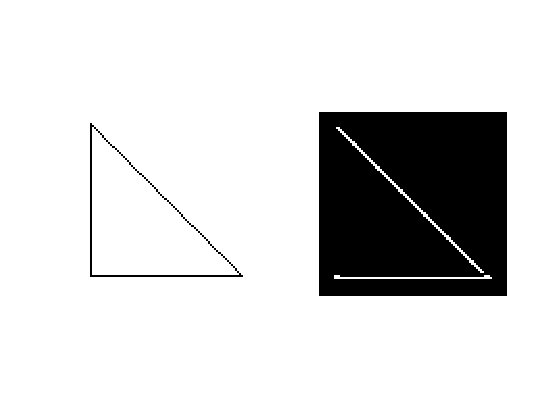

I = imread('trojuhelnik.png');

w = [-1 -2 -1; 
      0 0 0 ; 
      1 2 1];
I2 = imfilter(I,w,'corr','same');

figure
subplot(1,2,1)
imshow(I,[])
subplot(1,2,2)
imshow(I2,[])

#### svisle hrany

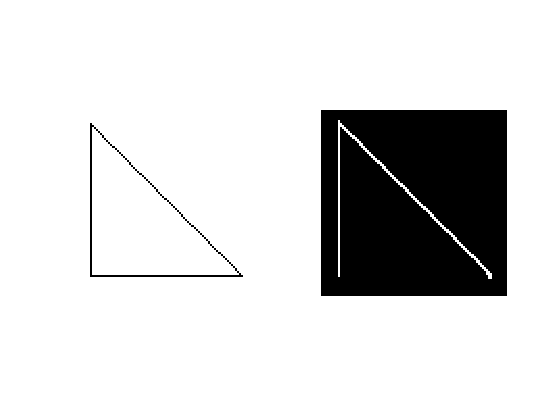

I = imread('trojuhelnik.png');
w = [-1 0 1; 
     -2 0 2 ; 

     -1 0 1];
I2 = imfilter(I,w,'corr','same');

figure
subplot(1,2,1)
imshow(I,[])
subplot(1,2,2)
imshow(I2,[])


#### diagonalni hrany

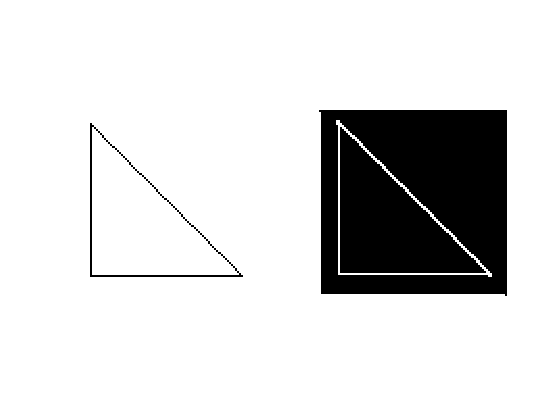

I = imread('trojuhelnik.png');
w = [0 1 2;
    -1 0 1; 
    -2 -1 0];
I2 = imfilter(I,w,'corr','same');


figure
subplot(1,2,1)
imshow(I,[])
subplot(1,2,2)
imshow(I2,[])

#### diagonalni hrany

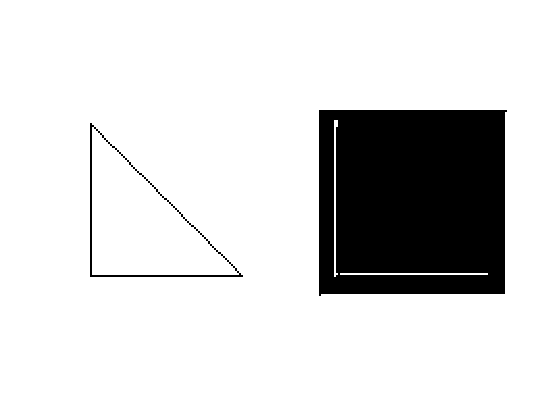

I = imread('trojuhelnik.png');
w = [2 1 0;
    1 0 -1; 
    0 -1 -2];
I2 = imfilter(I,w,'corr','same');

figure

subplot(1,2,1)
imshow(I,[])
subplot(1,2,2)
imshow(I2,[])

## UKOL 4

Vyberte vhodnou metodu a najdete hrany v nasledujicim obrazku

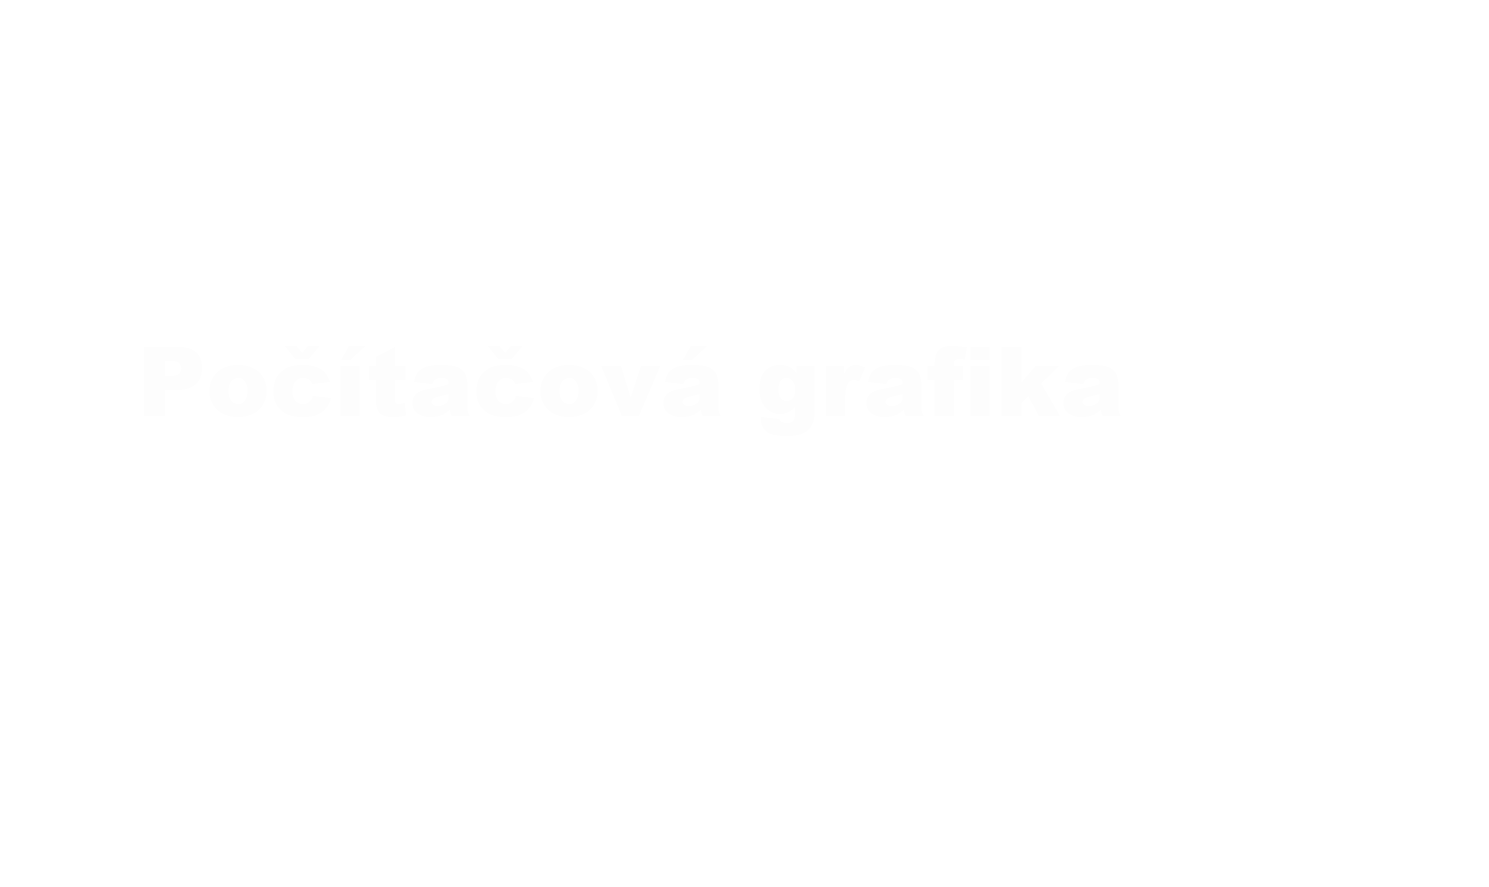

I3 = rgb2gray(imread('cv5-img3.png'));
figure,

imshow(I3);